# Sync. Rect. Loss Calculation - Resonant Link. OS

% This code implements a fast loss estimation for RL`s sync. rectifier.
% Version: 1.0 - Yi@Zurich, 2024 Mar. 1st

clc
clear

## Output definition

circuit = [];
circuit.fop     =   6.78e6  ;                   % Operating frequency of the rectifier;
circuit.Pout    =   5       ;                   % Output power of the rectifier. 
circuit.Vout    =   12       ;                   % DC output voltage of the rectifier.
circuit.topo    =   'FB'    ;                   % Topology of the rectifier, 'FB' - Full Bridge/ 'HB' - Half Bridge

## Switch candidates definition

FET = [];
FET.PN      =   {'EPC2040',     'EPC2216'};
FET.rdson   =   [24,            20               ]*1e-3;             % typical Rds-on used
FET.Ciss    =   [86             98               ]*1e-12;            % Read the number from datasheet (not the plot)
FET.Coss    =   [106            69               ]*1e-12;            % Read from datasheet (not the plot)
FET.Vg      =   5       ;                                            % gate voltage

## Calculation

% Loss calculation
[circuit,Loss] = RL_syncRectLossCal(circuit,FET);

% Switch selection and results output
[PsyncRec, FETindex] = min(Loss.Ptotal);

disp('Sync. Rectifier Loss Estimation');
disp(['Output Power: ',num2str(circuit.Pout),' W, ', 'DC Output Voltage: ',num2str(circuit.Vout),' V, ']);
disp(['Rectifier Topology: ',circuit.topoName]);
disp(['Switch Part Number: ',FET.PN{FETindex}]);
disp(['Totl Loss: ',num2str(Loss.Ptotal(FETindex)*1e3),' mW']);

disp('Loss Breakdown');
disp(['Conduction Loss: ',num2str(Loss.Pconduction(FETindex)*1e3),' mW']);
disp(['Ciss Loss: ',num2str(Loss.Pciss(FETindex)*1e3),' mW']);
disp(['Coss Loss: ',num2str(Loss.Pcoss(FETindex)*1e3),' mW']);
disp(['Driver Loss: ',num2str(Loss.Pdriver*1e3),' mW']);
disp(['FPGA and Sampling Circuit Loss: ',num2str(Loss.Panalog*1e3),' mW']);


## Functions

function [circuit,Loss] = RL_syncRectLossCal(circuit,FET)
    Loss = [];
    % Topology scaling
    if circuit.topo == ['FB']
        topoFactor = 4;
        circuit.topoName = 'Full Bridge';
    elseif circuit.topo == ['HB']
        topoFactor = 2;
        circuit.topoName = 'Half Bridge';
    else
        disp('Undefined rectifier topology.')
        keyboard;
    end

    %   Modelling explanation
    %   - Conduction Loss
    %   - Ciss loss
    %   - Coss loss
    %   - Driver loss
    %   - FPGA and sampling circuit loss
    
    % Conduction loss calculation
    Loss.Pconduction = topoFactor/2*(circuit.Pout./(circuit.Vout*topoFactor/pi/1.414)).^2.*FET.rdson;

    % Ciss loss calculation
    Loss.Pciss = topoFactor*0.5*(FET.Vg).^2.*FET.Ciss*circuit.fop; 

    % Coss loss calculation, assume 10% energy storage on the Coss will be
    % concumed
    Loss.Pcoss = topoFactor*0.5*(circuit.Vout).^2.*FET.Coss*0.1*circuit.fop; 

    % Driver loss
    % Read from the following datasheet:
    % Input-side VDD = 3.3 V/ Output-side VDD = 5V
    VDD_in = 3.3;
    VDD_out = 5;

    I_in = (0.17 + circuit.fop/1e6*0.0103)*1e-3;
    I_out= (0.20 + circuit.fop/1e6*0.0220)*1e-3;

    Loss.Pdriver = VDD_in*I_in + VDD_out*I_out;

[MAX12930/MAX12931 - Two-Channel, Low-Power, 3kVRMS and 5kVRMS Digital Isolators (mouser.com)](https://www.mouser.com/datasheet/2/609/MAX12930_MAX12931-3126253.pdf)

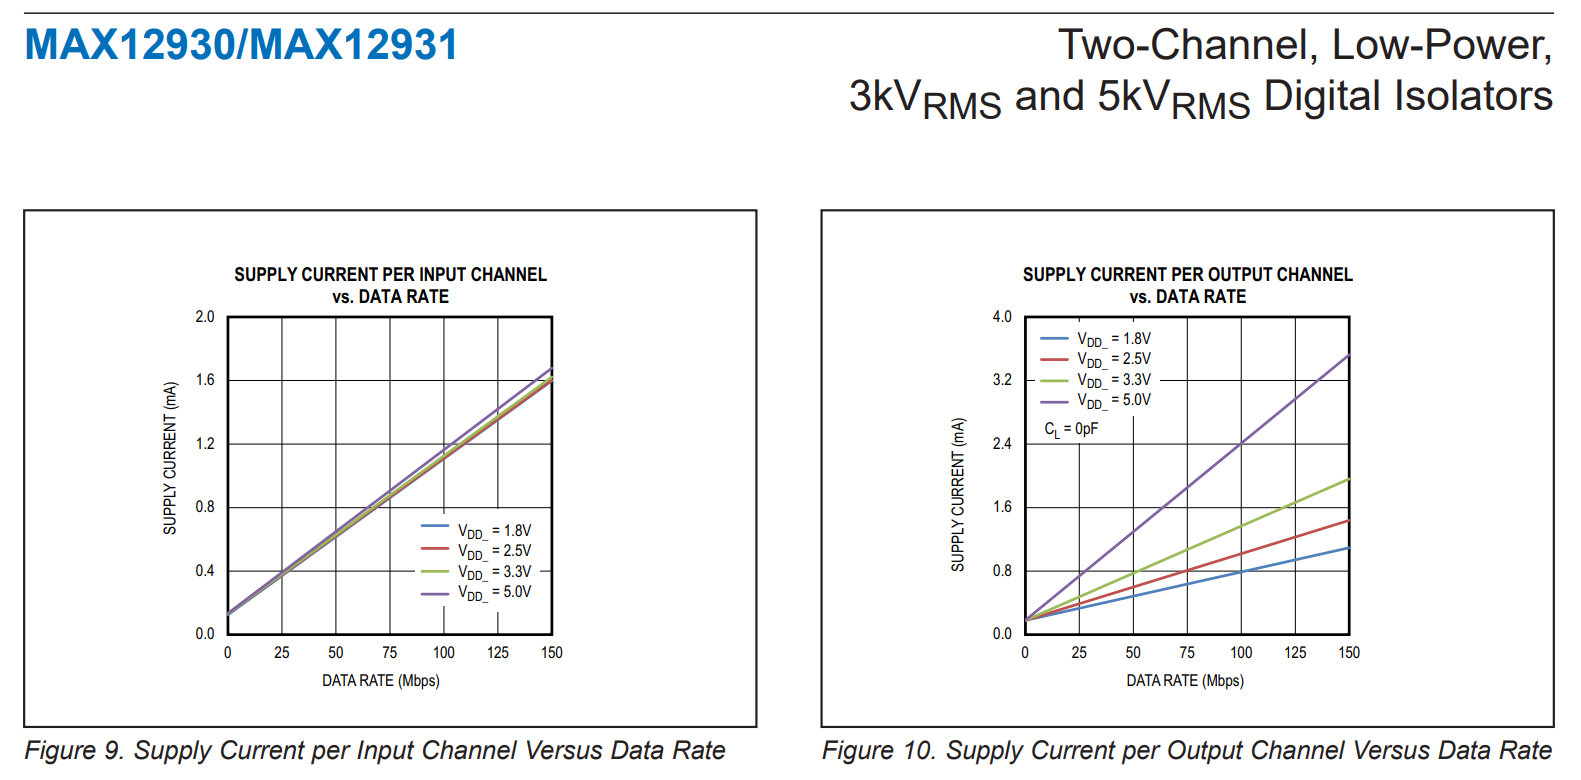

    % FPGA and Sampling circuit loss
    Loss.Panalog = 54e-3;
    
    % Total Loss
    Loss.Ptotal = (Loss.Panalog+Loss.Pdriver).*ones(1,length(FET.rdson))+Loss.Pconduction+Loss.Pciss + Loss.Pcoss;
        
end